% load data
load 'Cohort ER1.mat' % ER1 cohort data

load 'Cohort XFL.mat' % XFL cohort data

data=cohortER1; % create data variable
data

data = 144×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    cohortname
    cohortnum
    runum
    ratnums
    ratnames
    ratsamples
    tries
    matches
    wins
    nTransitions
    genopair
    duration
    binofitDIO


data=cohortXFL % create data variable

data = 405×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    cohortname
    cohortnum
    runum
    ratnums
    ratnames
    ratsamples
    tries
    matches
    wins
    nTransitions
    genopair
    duration
    binofitDIO


% Get unique days 
uniquedays=[];
convert_dates=cellfun(@(a) datenum(a,'dd-mm-yy'),{data.date})';
[days,ia,ic]=unique(convert_dates);

performance_wt=[]; % rewards/transitions (rat1 + rat2)
sem_wt=[]; % SEM 
performance_fx=[]; 
sem_fx=[];

rWt=[];
rFx=[];

binomean_wt=[];
binoCI_wt=[];

binomean_fx=[];
binoCI_fx=[];

for day=1:height(days) % iterate across days 
    
    temp_performance_wt=[]; % temporary vector containing rewards/transitions for each session from a given day 
    temp_performance_fx=[];
    
    temp_binomean_wt=[];
    temp_binomean_fx=[];
    
    temp_binoCI_wt=[];
    temp_binoCI_fx=[];
    
    for genotype=[0 2] % 0: Wt-Wt; 2: Fx-Fx % iterate across genotypes (pairs)
    
        sessions=data(ic==day,:); % extract all sessions from a given day 
        sessions=sessions(cellfun(@(a) a==genotype,{sessions.genopair}),:); % filter sessions by genotype 
        
        if isempty(sessions) && genotype==0
            temp_binoCI_wt=[nan nan];
            
        elseif isempty(sessions) && genotype==2
            temp_binoCI_fx=[nan nan];
        end
        
        for session=1:height(sessions) % iterate across sessions 
            rewards=sum(sessions(session).ratsamples{1}.Reward); % extract number of rewards 
            transitions=sum(sessions(session).nTransitions); % extract number of transitions (rat1 + rat2)
            
            if genotype==0
                temp_performance_wt(end+1)=rewards/transitions; % add session performance to temporary vector (we gonna obtain a daily average at the end) 
                rWt(end+1)=rewards;
                temp_binomean_wt(end+1)=sessions(session).binofitDIO.binomean;
                temp_binoCI_wt=[temp_binoCI_wt;sessions(session).binofitDIO.binoBounds];
 
                
            else
                temp_performance_fx(end+1)=rewards/transitions;
                temp_binomean_fx(end+1)=sessions(session).binofitDIO.binomean;
                temp_binoCI_fx=[temp_binoCI_fx;sessions(session).binofitDIO.binoBounds];
                rFx(end+1)=rewards;
               
            end
            
        end
    
    end
    
    performance_wt(end+1)=mean(temp_performance_wt); % get daily average performance 
    sem_wt(end+1)=std(temp_performance_wt,1)/sqrt(length(temp_performance_wt));
    
    binomean_wt(end+1)=mean(temp_binomean_wt);
    binoCI_wt=[binoCI_wt;mean(temp_binoCI_wt,1)];
    
    
    performance_fx(end+1)=mean(temp_performance_fx);
    sem_fx(end+1)=std(temp_performance_fx,1)/sqrt(length(temp_performance_fx));
    
    binomean_fx(end+1)=mean(temp_binomean_fx);
    binoCI_fx=[binoCI_fx;mean(temp_binoCI_fx,1)];
    

        
    
end

performance_wt

performance_wt =     0.0303    0.1062    0.0909    0.1000    0.1111    0.0625    0.2308    0.0435    0.1034    0.0526    0.1154    0.0714    0.0556    0.1000    0.1026    0.1558    0.0526    0.1628    0.1290    0.2133    0.1538    0.1525    0.0870    0.1770    0.0645       NaN


data

data = 405×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    cohortname
    cohortnum
    runum
    ratnums
    ratnames
    ratsamples
    tries
    matches
    wins
    nTransitions
    genopair
    duration
    binofitDIO


% Remove days 13 and 14 of cohortER1 data (animals were on free-fed during
% those runs)
performance_wt([13 14])=[];performance_fx([13 14])=[];
sem_wt([13 14])=[];sem_fx([13 14])=[];
binomean_wt([13 14])=[];binomean_fx([13 14])=[];
binoCI_wt([13 14],:)=[];binoCI_fx([13 14],:)=[];

% Fill NaN values for missing days cohortXFL data 
performance_wt=fillmissing(performance_wt,"linear");performance_fx=fillmissing(performance_fx,"linear");
sem_wt=fillmissing(sem_wt,"linear");sem_fx=fillmissing(sem_fx,"linear")

sem_fx =     0.0716    0.0358         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0020    0.0040         0         0         0         0         0         0         0         0    0.0302         0         0         0         0         0         0         0         0         0         0         0         0         0         0


binomean_wt=fillmissing(binomean_wt,"linear");binomean_fx=fillmissing(binomean_fx,"linear")

binomean_fx =     0.6629    0.5814    0.5000    0.7500    0.7083    0.6667    0.6667    0.6154    0.7333    0.7778    0.4667    0.5000    0.5000    0.5333    0.6250    0.7143    0.6471    0.5455    0.5625    0.4737    0.5758    0.6875    0.3929    0.6316    0.4545    0.4523    0.4500    0.5000    0.5500    0.5455    0.5000    0.5926    0.4706    0.4737    0.5789    0.4984    0.4737    0.5484    0.3714    0.4444    0.3833    0.5926    0.5455    0.4688    0.4857    0.3889    0.7353    0.4324    0.7949    0.6800


binoCI_wt=fillmissing(binoCI_wt,"linear");binoCI_fx=fillmissing(binoCI_fx,"linear")

binoCI_fx =     0.3691    0.8775
    0.3078    0.8155
    0.2465    0.7535
    0.3491    0.9681
    0.3795    0.9174
    0.4099    0.8666
    0.3489    0.9008
    0.3158    0.8614
    0.4490    0.9221
    0.5236    0.9359



% Show only data from day 35 onwards (when 100 reward contingecy got
% implemented)

performance_wt=performance_wt(35:end);performance_fx=performance_fx(35:end)

performance_fx =     0.3103    0.2323    0.1455    0.3191    0.1250    0.1176    0.1807    0.2558    0.1818    0.1915    0.0962    0.1600    0.3276    0.1509    0.2319    0.2439    0.1429    0.3947    0.0714    0.1667    0.1288    0.1005    0.1267    0.1261    0.0960    0.1194    0.1510    0.1139    0.1075    0.1438    0.1518


sem_wt=sem_wt(35:end);sem_fx=sem_fx(35:end)

sem_fx =          0    0.0302         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0321    0.0124    0.0124    0.0061    0.0109    0.0332    0.0087    0.0058    0.0186    0.0050    0.0126


binomean_wt=binomean_wt(35:end);binomean_fx=binomean_fx(35:end)

binomean_fx =     0.5789    0.4984    0.4737    0.5484    0.3714    0.4444    0.3833    0.5926    0.5455    0.4688    0.4857    0.3889    0.7353    0.4324    0.7949    0.6800    0.6800    0.7273    0.4483    0.4918    0.6099    0.5723    0.5586    0.5569    0.4717    0.4768    0.5531    0.4900    0.4868    0.4875    0.5158


binoCI_fx =     0.3350    0.7975
    0.3490    0.6489
    0.3098    0.6418
    0.3603    0.7268
    0.2147    0.5508
    0.2794    0.6190
    0.2607    0.5179
    0.3880    0.7761
    0.3221    0.7561
    0.2909    0.6526


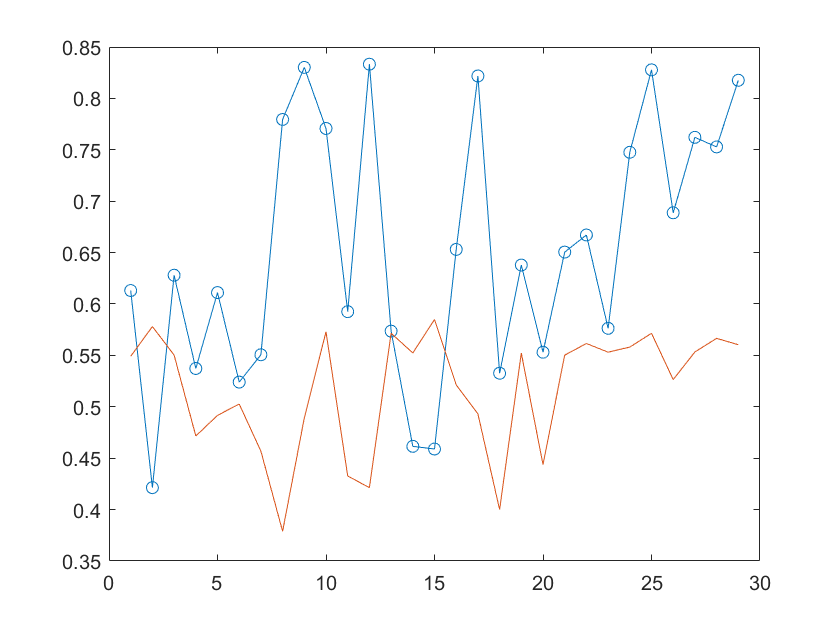

performance_wt =     0.3950    0.1010    0.1316    0.1431    0.1384    0.1834    0.1981    0.2164    0.1847    0.1997    0.2064    0.1694    0.1354    0.1815


sem_wt =          0         0         0    0.0189    0.0143    0.0126    0.0155    0.0130    0.0162    0.0050    0.0120    0.0116    0.0176    0.0084


performance_fx =     0.3947    0.0714    0.1667    0.1288    0.1005    0.1267    0.1261    0.0960    0.1194    0.1510    0.1139    0.1075    0.1438    0.1518


sem_fx =          0         0         0    0.0321    0.0124    0.0124    0.0061    0.0109    0.0332    0.0087    0.0058    0.0186    0.0050    0.0126


performance_wt =     0.4238    0.1295    0.1838    0.1485    0.2175    0.2127    0.2071    0.2667    0.3028    0.2312    0.2551    0.2533    0.2849


sem_wt =     0.0093    0.0007    0.0065    0.0096    0.0208    0.0264    0.0189    0.0109    0.0174    0.0191    0.0102    0.0081    0.0040


performance_fx =     0.2898    0.1899    0.1660    0.1468    0.1464    0.1747


sem_fx =     0.0239    0.0034    0.0244    0.0066    0.0014    0.0111


binoCI_wt=binoCI_wt(35:end,:);binoCI_fx=binoCI_fx(35:end,:)

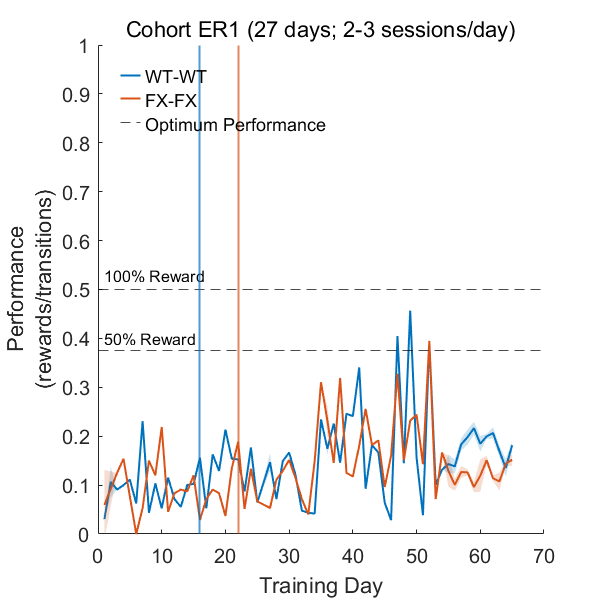

% Plot Performance: Rewards/Transitions (rat1 + rat2) (Cohort ER1)
mycolors=lines(3);
figure;
plot(performance_wt,'Color',mycolors(1,:),'linewidth',1);
hold on
plot(performance_fx,'Color',mycolors(2,:),'linewidth',1);
yline((0.25+0.5)/2,'k--');
yline(0.50,'k--');
%plot([1 17],[0.5 0.5],'k-','linewidth',2);
%plot([18 20],[0.25 0.25],'k-','linewidth',2);
%plot([53 60],[0.25 0.25],'k-','linewidth',2);
fill([(1:length(performance_wt))';flipud((1:length(performance_wt))')],[(performance_wt'-sem_wt');flipud((performance_wt'+sem_wt'))],mycolors(1,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
fill([(1:length(performance_fx))';flipud((1:length(performance_fx))')],[(performance_fx'-sem_fx');flipud((performance_fx'+sem_fx'))],mycolors(2,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
xlabel('Training Day');ylabel({'Performance';'(rewards/transitions)'});
ylim([0 1]);
%xlim([0 30]);
xline(16,'Color',mycolors(1,:),'linewidth',1);
xline(22,'Color',mycolors(2,:),'linewidth',1);

%yline(0.25,'k-');
%yline(0.50,'k-');
text(1,0.53,'100% Reward','FontSize',8);
text(1,0.40,'50% Reward','FontSize',8);
lg=legend("WT-WT","FX-FX","Optimum Performance",'location','northwest');
lg.Box='off';
lg.ItemTokenSize=[10 10];
box off

set(gcf,'Position',[0 0 400 400]);
title('Cohort ER1 (27 days; 2-3 sessions/day)','FontWeight','normal');

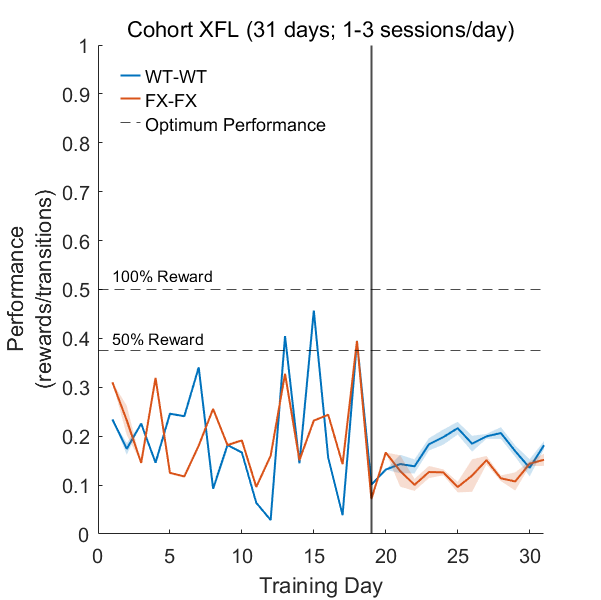

% Plot Performance: Rewards/Transitions (rat1 + rat2) (Cohort XFL)
mycolors=lines(3);
figure;
plot(performance_wt,'Color',mycolors(1,:),'linewidth',1);
hold on
plot(performance_fx,'Color',mycolors(2,:),'linewidth',1);
yline((0.25+0.5)/2,'k--');
yline(0.50,'k--');
%plot([1 17],[0.5 0.5],'k-','linewidth',2);
%plot([18 20],[0.25 0.25],'k-','linewidth',2);
%plot([53 60],[0.25 0.25],'k-','linewidth',2);
fill([(1:length(performance_wt))';flipud((1:length(performance_wt))')],[(performance_wt'-sem_wt');flipud((performance_wt'+sem_wt'))],mycolors(1,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
fill([(1:length(performance_fx))';flipud((1:length(performance_fx))')],[(performance_fx'-sem_fx');flipud((performance_fx'+sem_fx'))],mycolors(2,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
xlabel('Training Day');ylabel({'Performance';'(rewards/transitions)'});
ylim([0 1]);
%xlim([0 30]);

%xline(35,'k-','linewidth',1);
xlim([0 31])

xline(53-34,'k-','linewidth',1);
%xline(53,'k-','linewidth',1);

%yline(0.25,'k-');
%yline(0.50,'k-');
text(1,0.53,'100% Reward','FontSize',8);
text(1,0.40,'50% Reward','FontSize',8);
lg=legend("WT-WT","FX-FX","Optimum Performance",'location','northwest');
lg.Box='off';
lg.ItemTokenSize=[10 10];
box off

set(gcf,'Position',[0 0 400 400]);
title('Cohort XFL (31 days; 1-3 sessions/day)','FontWeight','normal');
% Save Figures
saveas(gcf,'H:\Social W Behavioral Data\Cohort-XFL\Results\Cohort-XFL-Performance.png');

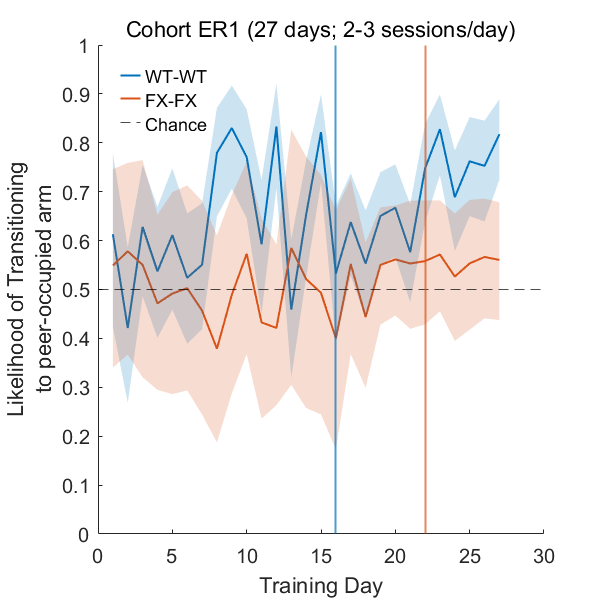

% Plot Performance: Rewards/Transitions (rat1 + rat2) (Cohort ER1)
mycolors=lines(3);
figure;
plot(binomean_wt,'Color',mycolors(1,:),'linewidth',1);
hold on
plot(binomean_fx,'Color',mycolors(2,:),'linewidth',1);
% yline((0.25+0.5)/2,'k--');
yline(0.50,'k--');
% %plot([1 17],[0.5 0.5],'k-','linewidth',2);
% %plot([18 20],[0.25 0.25],'k-','linewidth',2);
% %plot([53 60],[0.25 0.25],'k-','linewidth',2);
fill([(1:length(binomean_wt))';flipud((1:length(binomean_wt))')],[binoCI_wt(:,1);flipud(binoCI_wt(:,2))],mycolors(1,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
fill([(1:length(binomean_fx))';flipud((1:length(binomean_fx))')],[binoCI_fx(:,1);flipud(binoCI_fx(:,2))],mycolors(2,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
xlabel('Training Day');ylabel({'Likelihood of Transitioning';'to peer-occupied arm'});
ylim([0 1]);
% %xlim([0 30]);
xline(16,'Color',mycolors(1,:),'linewidth',1);
xline(22,'Color',mycolors(2,:),'linewidth',1);
% 
% %yline(0.25,'k-');
% %yline(0.50,'k-');
% text(1,0.53,'100% Reward','FontSize',8);
% text(1,0.40,'50% Reward','FontSize',8);
lg=legend("WT-WT","FX-FX","Chance",'location','northwest');
lg.Box='off';
lg.ItemTokenSize=[10 10];
box off
% 
set(gcf,'Position',[0 0 400 400]);
title('Cohort ER1 (27 days; 2-3 sessions/day)','FontWeight','normal');

% Save Figures
saveas(gcf,'H:\Social W Behavioral Data\Cohort-ER1\Results\Cohort-ER1-Likelihood.png');

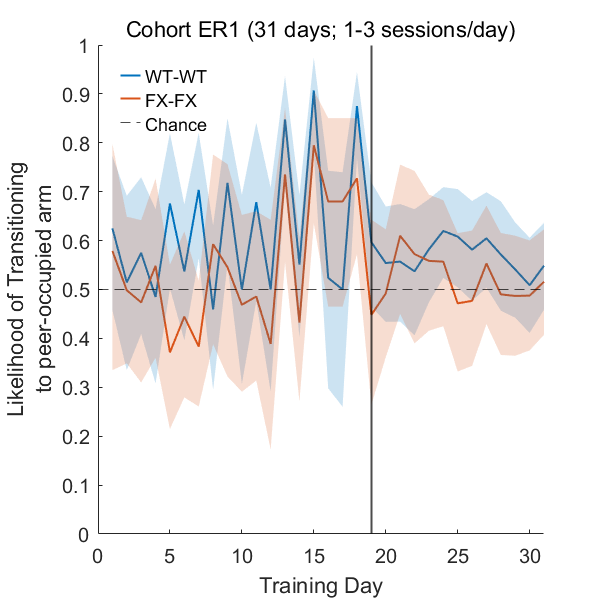

% Plot Performance: Rewards/Transitions (rat1 + rat2) (Cohort XFL)
mycolors=lines(3);
figure;
plot(binomean_wt,'Color',mycolors(1,:),'linewidth',1);
hold on
plot(binomean_fx,'Color',mycolors(2,:),'linewidth',1);
% yline((0.25+0.5)/2,'k--');
yline(0.50,'k--');
% %plot([1 17],[0.5 0.5],'k-','linewidth',2);
% %plot([18 20],[0.25 0.25],'k-','linewidth',2);
% %plot([53 60],[0.25 0.25],'k-','linewidth',2);
fill([(1:length(binomean_wt))';flipud((1:length(binomean_wt))')],[binoCI_wt(:,1);flipud(binoCI_wt(:,2))],mycolors(1,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
fill([(1:length(binomean_fx))';flipud((1:length(binomean_fx))')],[binoCI_fx(:,1);flipud(binoCI_fx(:,2))],mycolors(2,:),'linestyle','none','FaceAlpha',0.2,'EdgeColor','none');
xlabel('Training Day');ylabel({'Likelihood of Transitioning';'to peer-occupied arm'});
ylim([0 1]);
% %xlim([0 30]);

xline(53-34,'k-','linewidth',1);
xlim([0 31]);
% 
% %yline(0.25,'k-');
% %yline(0.50,'k-');
% text(1,0.53,'100% Reward','FontSize',8);
% text(1,0.40,'50% Reward','FontSize',8);
lg=legend("WT-WT","FX-FX","Chance",'location','northwest');
lg.Box='off';
lg.ItemTokenSize=[10 10];
box off
% 
set(gcf,'Position',[0 0 400 400]);
title('Cohort ER1 (31 days; 1-3 sessions/day)','FontWeight','normal');

% Save Figures
saveas(gcf,'H:\Social W Behavioral Data\Cohort-XFL\Results\Cohort-XFL-Likelihood.png');

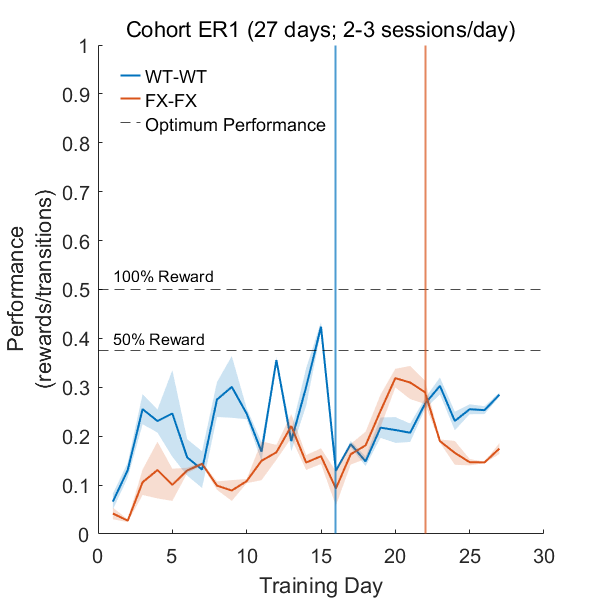

% Save Figures
saveas(gcf,'H:\Social W Behavioral Data\Cohort-ER1\Results\Cohort-ER1-Performance.png');